# HOTFIRE TEST DATA ANALYSIS

## Get Test Data

csvPath = "C:\Repos\iclr_simulations\code\electronic_pressure_regulator\matlab_code\Hotfire\ember_002_hotfire_trimmed.csv";

opts = detectImportOptions(csvPath);
opts.VariableNamingRule = 'preserve'; 
dataTableHeader = readtable(csvPath, opts);
dataStructArray = table2struct(dataTableHeader);

hotfireDataStruct = table2struct(dataTableHeader, 'ToScalar', true)

hotfireDataStruct = struct with fields:
                      Time: [152×1 double]
                   ox_n2_p: [152×1 double]
                 ox_tank_p: [152×1 double]
             ox_ereg_angle: [152×1 double]
            ox_feedforward: [152×1 double]
      ox_proportional_term: [152×1 double]
                     ox_kp: [152×1 double]
                 fuel_n2_p: [152×1 double]
               fuel_tank_p: [152×1 double]
           fuel_ereg_angle: [152×1 double]
          fuel_feedforward: [152×1 double]
    fuel_proportional_term: [152×1 double]
                   fuel_kp: [152×1 double]
                 chamber_p: [152×1 double]
                  ox_inj_p: [152×1 double]
                fuel_inj_p: [152×1 double]
                fuel_inj_T: [152×1 double]
                 fuel_vdot: [152×1 double]
          impulse_integral: [152×1 double]
             ox_main_angle: [152×1 double]
           fuel_main_angle: [152×1 double]
                    thrust: [152×1 double]
              

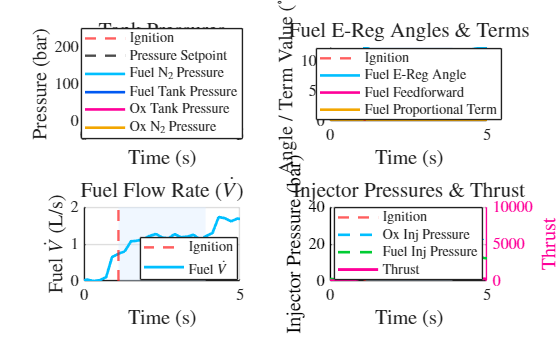

% Set LaTeX as default interpreter and increase global font sizes
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultAxesFontSize', 14);       % Increased axis tick font size
set(groot, 'defaultLegendFontSize', 13);     % Increased legend font size

fig = figure('Name', 'Hotfire Data Analysis (0-5s)', 'NumberTitle', 'off', 'Color', 'w');
t = hotfireDataStruct.Time;

% Defined parameters
t_ignition = 1.10415;
t_burn_end = 3.9;

% Bright high-contrast color palette
c_cyan    = [0.0, 0.75, 1.0];
c_magenta = [1.0, 0.0,  0.6];
c_yellow  = [0.95, 0.65, 0.0]; % Darker yellow for visibility on white background
c_green   = [0.0, 0.8,  0.2];
c_red     = [1.0, 0.1,  0.1];
c_blue    = [0.0, 0.35, 0.95];

%% 1. Tank Pressures
subplot(2,2,1);
hold on;
xregion(t_ignition, t_burn_end, 'FaceColor', [0.85 0.92 1.0], 'FaceAlpha', 0.4, 'HandleVisibility', 'off');
xline(t_ignition, '--', 'DisplayName', 'Ignition', ...
      'Color', c_red, 'LineWidth', 1.8, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'top', 'FontSize', 14);
yline(45, '--', 'Pressure Setpoint', 'LineWidth', 1.8, 'Color', 'k', ...
      'LabelHorizontalAlignment', 'left', 'DisplayName', 'Pressure Setpoint', 'FontSize', 14);

plot(t, hotfireDataStruct.fuel_n2_p, 'LineWidth', 2, 'Color', c_cyan, 'DisplayName', 'Fuel $\mathrm{N_2}$ Pressure');
plot(t, hotfireDataStruct.fuel_tank_p, 'LineWidth', 2, 'Color', c_blue, 'DisplayName', 'Fuel Tank Pressure');
plot(t, hotfireDataStruct.ox_tank_p, 'LineWidth', 2, 'Color', c_magenta, 'DisplayName', 'Ox Tank Pressure');
plot(t, hotfireDataStruct.ox_n2_p, 'LineWidth', 2, 'Color', c_yellow, 'DisplayName', 'Ox $\mathrm{N_2}$ Pressure');
hold off;

title('Tank Pressures', 'FontSize', 16);
xlabel('Time (s)', 'FontSize', 15);
ylabel('Pressure (bar)', 'FontSize', 15);
xlim([0 5]);
grid on;
legend('Location', 'best');

%% 2. Fuel E-Reg Angles & Terms
subplot(2,2,2);
hold on;
xregion(t_ignition, t_burn_end, 'FaceColor', [0.85 0.92 1.0], 'FaceAlpha', 0.4, 'HandleVisibility', 'off');
xline(t_ignition, '--', 'DisplayName', 'Ignition', ...
      'Color', c_red, 'LineWidth', 1.8, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'top', 'FontSize', 14);

plot(t, hotfireDataStruct.fuel_ereg_angle / 10, 'LineWidth', 2, 'Color', c_cyan, 'DisplayName', 'Fuel E-Reg Angle');
plot(t, hotfireDataStruct.fuel_feedforward / 10, 'LineWidth', 2, 'Color', c_magenta, 'DisplayName', 'Fuel Feedforward');
plot(t, hotfireDataStruct.fuel_proportional_term / 10, 'LineWidth', 2, 'Color', c_yellow, 'DisplayName', 'Fuel Proportional Term');
hold off;

title('Fuel E-Reg Angles \& Terms', 'FontSize', 16);
xlabel('Time (s)', 'FontSize', 15);
ylabel('Angle / Term Value ($^\circ$)', 'FontSize', 15);
xlim([0 5]);
grid on;
legend('Location', 'best');

%% 3. Fuel Vdot
subplot(2,2,3);
hold on;
xregion(t_ignition, t_burn_end, 'FaceColor', [0.85 0.92 1.0], 'FaceAlpha', 0.4, 'HandleVisibility', 'off');
xline(t_ignition, '--', 'DisplayName', 'Ignition', ...
      'Color', c_red, 'LineWidth', 1.8, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'top', 'FontSize', 14);

plot(t, hotfireDataStruct.fuel_vdot, 'LineWidth', 2, 'Color', c_cyan, 'DisplayName', 'Fuel $\dot{V}$');
hold off;

title('Fuel Flow Rate ($\dot{V}$)', 'FontSize', 16);
xlabel('Time (s)', 'FontSize', 15);
ylabel('Fuel $\dot{V}$ (L/s)', 'FontSize', 15);
xlim([0 5]);
grid on;
legend('Location', 'best');

%% 4. Injector Pressures & Thrust
subplot(2,2,4);
ax4_1 = gca;
hold(ax4_1, 'on');
xregion(t_ignition, t_burn_end, 'FaceColor', [0.85 0.92 1.0], 'FaceAlpha', 0.4, 'HandleVisibility', 'off');
xline(t_ignition, '--', 'DisplayName', 'Ignition', ...
      'Color', c_red, 'LineWidth', 1.8, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'top', 'FontSize', 14);

yyaxis left
plot(t, hotfireDataStruct.ox_inj_p, '--', 'LineWidth', 2, 'Color', c_cyan, 'DisplayName', 'Ox Inj Pressure');
plot(t, hotfireDataStruct.fuel_inj_p, '--', 'LineWidth', 2, 'Color', c_green, 'DisplayName', 'Fuel Inj Pressure');
ylabel('Injector Pressure (bar)', 'FontSize', 15);
ax4_1.YColor = [0 0 0];

yyaxis right
plot(t, -hotfireDataStruct.thrust, '-', 'LineWidth', 2.2, 'Color', c_magenta, 'DisplayName', 'Thrust');
ylabel('Thrust', 'FontSize', 15);
ax4_2 = gca;
ax4_2.YColor = c_magenta;

hold(ax4_1, 'off');
title('Injector Pressures \& Thrust', 'FontSize', 16);
xlabel('Time (s)', 'FontSize', 15);
xlim([0 5]);
grid on;
legend('Location', 'best');


%% Save Figure
% savefig(fig, 'Hotfire_Data_Analysis.fig');
% exportgraphics(fig, 'Hotfire_Data_Analysis.png', 'Resolution', 1920);



